# IMAGE PROCESSING OF DEWETTING FROM VIDEO 

Takes a ".avi" video file, creates a plot of normalized area vs time. Saves an "_Area.txt" file that stores the analyzed data and can be passed into the "dataprocessing" file for further processing and analysis.

% NOTE: this program requires Matlab "image processing toolbox" to run on Matlab 2020a

% Last tested: 07/22/2020
% Version: Matlab 2020a                     

% July 22, 2020
% Modified by Vincent Xia

## Clear everything

clear variables global;
close all hidden;
clc;
warning('off','all'); %Suppress warnings for faster exec.

## Input dialog for video filename

[file,path] = uigetfile('*.avi'); %choose .avi file (can change format if needed)

input_dialog = inputdlg({'Remove objects smaller than X pixels 100-1000 ',...
    'Show frames?(1=T,0=F)','Skip Frames [1-1000]','Initial frame above surface',...
    'Plot video? (0=no, 1=yes)','Select video frame for area analysis'},'Sample',...
    [1 50; 1 50;1 20;1 20;1 20;1 20],{'250','0','3','40','0','2500'});
% remove objects smaller than X = will not designate a few pixels as
% wet/dry (reduces noise)

% Show frames: yes = see analysis as it goes (slows analysis) no = no
% frames shown (faster)

% Skip frames = # of frames skipped between analysis (smaller file)

%Initial frame above surface = first frame where dome is exposed (doesn't
%count previous frames as part of the time)

% Plot video: Change to 1 for getting a video of the plot; else keep 0 to speed up execution.

% Video frame for area analysis: Background frame for defining total area; pick frame 
                                 % after edge 'gravity-driven' dewetting occurs, and once
                                 % interference patterns begin

fname=strcat(path,file); % gets file name from uigetfile

## Input dialog for video type

analysis_type = inputdlg({'New or old software?(1=New,0=Old)','Lubricin or Water?(1=lubricin, 0=water)',...
                          'Output analyzed frames?(1=no, 0=yes)',...
                          'Output individual masks video?(1=no, 0=yes)'},'Analysis Type', [1 40; 1 40; 1 40; 1 40], {'1','1','1','1'});

%New or old software: Old uEye Cockpit laptop software or New Thorcam
%software from 2/25/2020 onwards

%Water or lubricin: Which are you measuring dewetting with?

## Parameters for image processing

remove_Pixels = str2double(input_dialog{1}); %gets this from input dialog
show_frames = str2double(input_dialog{2}); %gets this from input dialog
skip_frame = str2double(input_dialog{3}); %gets this from input dialog
t_0=str2double(input_dialog{4});   % gets this from input dialog
plot_video=str2double(input_dialog{5}); %gets this from input dialog
area_frame=str2double(input_dialog{6}); % Background frame for defining total area; pick frame 
                                        % after edge 'gravity-driven' dewetting occurs, and once
                                        % interference patterns begin
                                                                              
bg=t_0+5; % Keep at t_0 for videos with fast dewetting

sftwre_type = str2double(analysis_type{1}); %gets this from analysis_type input dialog
liquid_type = str2double(analysis_type{2}); %gets this from analysis_type input dialog
outputAnalyze = str2double(analysis_type{3}); %tells us whether or not to print an mp4 of analyzed frames from original video
outputMasks = str2double(analysis_type{4}); %tells us whether or not to print an mp4 of individual masks from video


%Theshold values for hue, saturation, value analysis (use Threshold Check
%to test values)

if sftwre_type == 0  %Old uEye Cockpit software
    if liquid_type == 1 %DI water
        % Used "DIWater HPL3 RT2" file from 2-21-2020, frame 1000 to obtain
        % threshold values  
        hueThresholdLow = 0;
        hueThresholdHigh = 1;
        saturationThresholdLow = 0;
        saturationThresholdHigh = 1;
        valueThresholdLow = 0.7;
        valueThresholdHigh = 1;   
    elseif liquid_type == 0 %lubricin    
        %Used ".5 ugml lubricin DS HPL 2 37C 1" from 1-20-2020,frame 2085
        %to obtain threshold values
        hueThresholdLow = .4;
        hueThresholdHigh = .5;
        saturationThresholdLow = .3;
        saturationThresholdHigh = .4;
        valueThresholdLow = 0.7;
        valueThresholdHigh = 1;
    end
elseif sftwre_type == 1 %New Thorcam software
    if liquid_type == 0 %DI Water

        % From 07-05-20 HPL3 DIWater Test 2 file
        hueThresholdLow = 0;
        hueThresholdHigh = 1;
        saturationThresholdLow = 0;
        saturationThresholdHigh = 1;
        valueThresholdLow = 0.659;
        valueThresholdHigh = 1;
        
    elseif liquid_type == 1 %lubricin

% %     For 07-18-20 1ugmL HPL1 NR
%         hueThresholdLow = .404;
%         hueThresholdHigh = .496;
%         saturationThresholdLow = .147;
%         saturationThresholdHigh = .236;
%         valueThresholdLow = .502;
%         valueThresholdHigh = .780;
        
    % For 07-19-20 .5 ugmL HPL1 NR (less discriminatory)
        hueThresholdLow = .410;
        hueThresholdHigh = .554;
        saturationThresholdLow = .104;
        saturationThresholdHigh = .271;
        valueThresholdLow = .439;
        valueThresholdHigh = .780;

    end 
end



## Video Import

video=VideoReader(fname); %starts reading video
fname=fname(1:end-4); %removes .avi or other file extension from filename
nframes=video.NumFrames; % gets # of frames in video
input_fps=video.FrameRate; % gets frames/second in initial video
vidHeight = video.Height; %gets video height
vidWidth = video.Width; %gets video width
background_frame = read(video, bg); %gets background frame in video (used for deleting background)

## Subtract Background

background=imcrop(rgb2gray(background_frame),[0,0,1024,768]); %Bground frame is when dome crosses interface, converts to grayscale

## Define output video parameters; open videos for writing

output_framerate=20; %output frame rate
outputVideo=VideoWriter(strcat(fname,'_maskVideo'),'MPEG-4'); %writes black/white video showing wet area (black) vs. dry area (white)
outputVideo.FrameRate = output_framerate; %sets output video frame rate

% ---Added by VX ---
analyzedVideo = VideoWriter(strcat(fname,'_analyzedOrigVideo'),'MPEG-4'); %writes video showing the original frames that were analyzed
analyzedVideo.FrameRate = 10; %sets output video frame rate | set skip_frame = 30

allMasks = VideoWriter(strcat(fname,'_allMasks'),'MPEG-4'); %writes video showing the original frames that were analyzed
allMasks.FrameRate = output_framerate; %sets output video frame rate



## Set total area

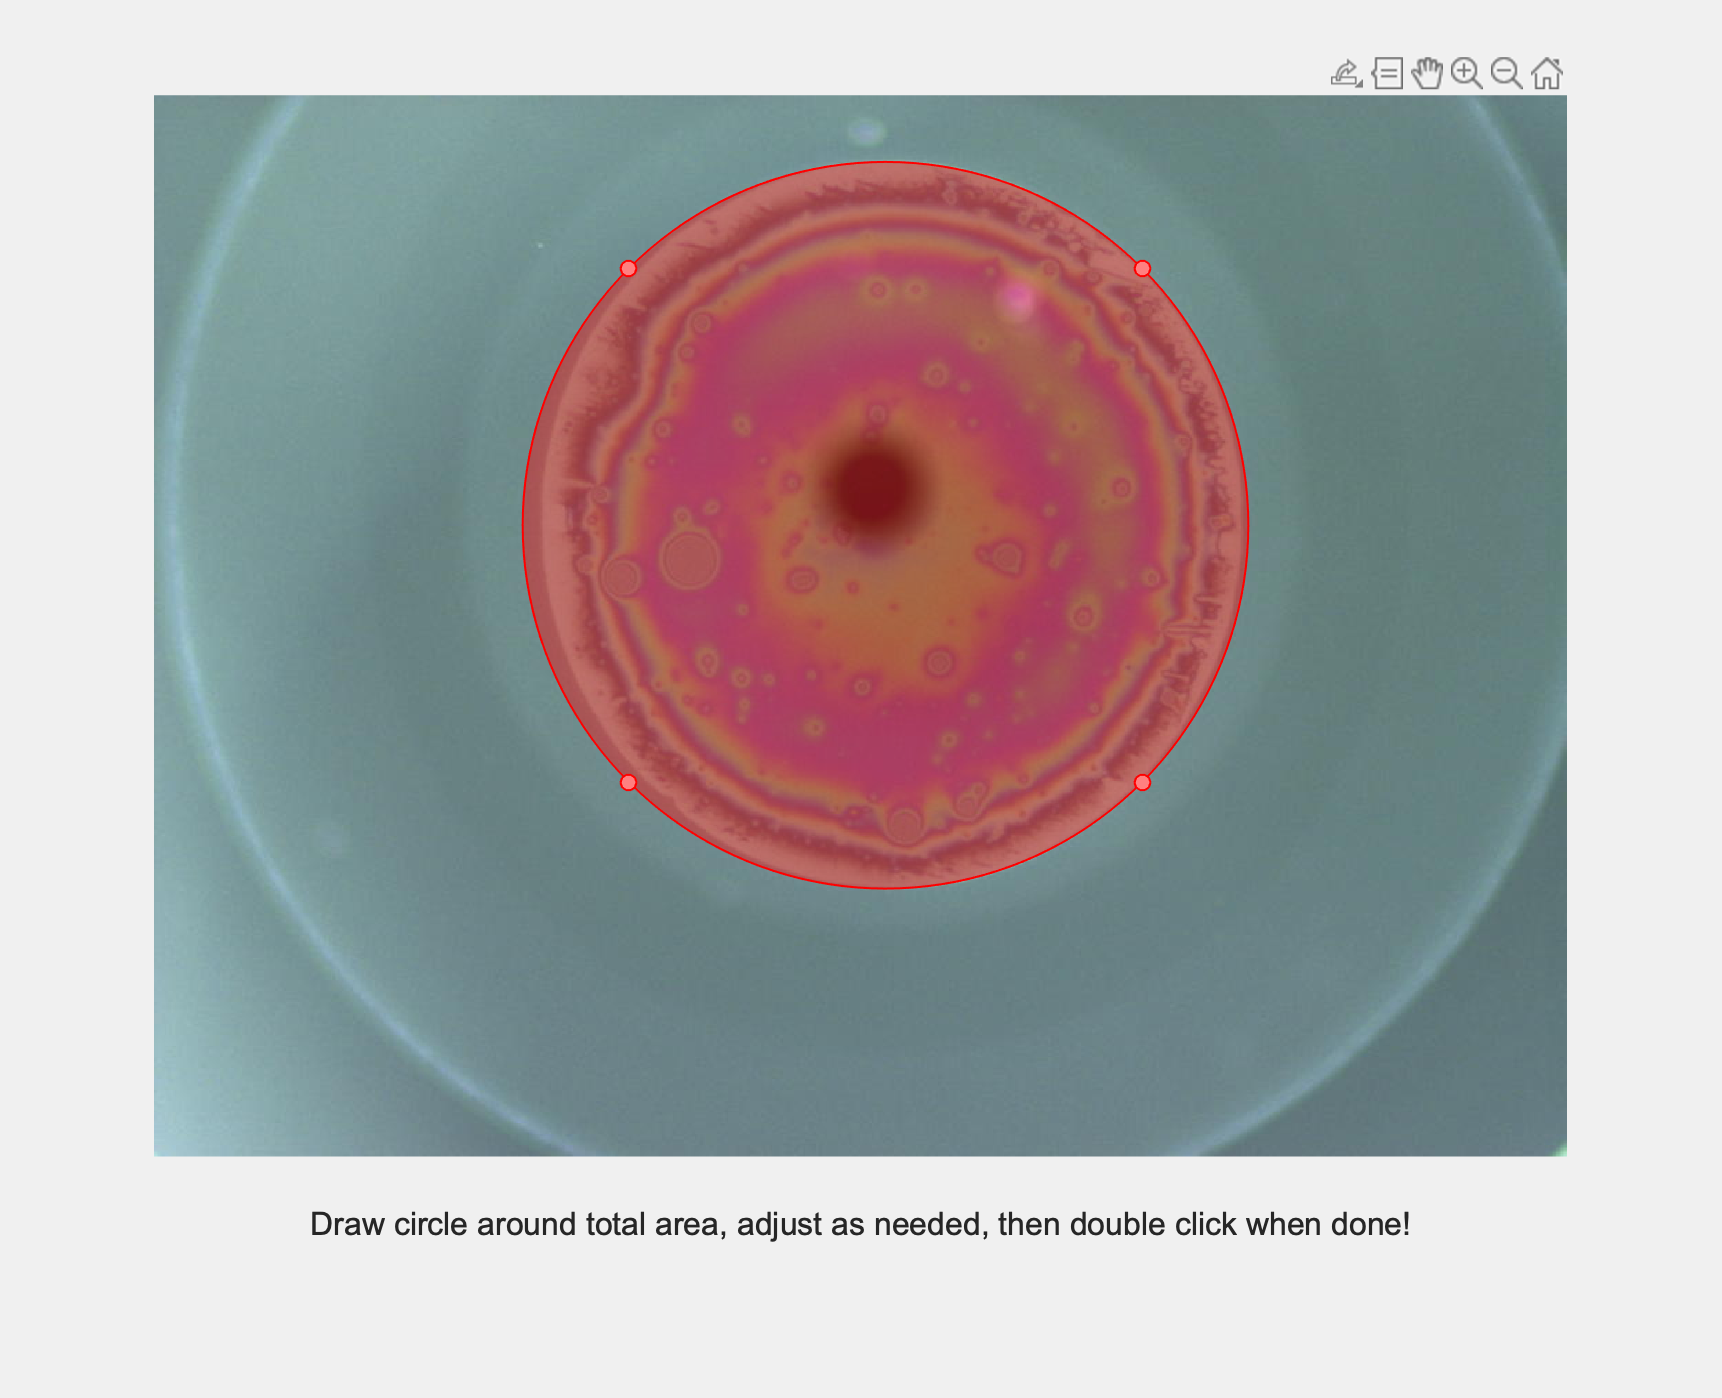

totalareaframe        = read(video,area_frame);                    % Read user specified frame for area analysis
totalareaframecropped = imcrop(totalareaframe,[0,0,1024,768]); % Crop last frame
totalareaframegray    = rgb2gray(totalareaframecropped);        % Grayscale last frame
trial = 0;
while trial >= 0
    imshow(totalareaframecropped);                                 % Show area frame as total area input
    xlabel('Draw circle around total area, adjust as needed, then double click when done!','FontSize',16,'FontName','Arial');
%     roi = drawassisted('Color','r','FaceAlpha',0.4);
    roi = drawcircle('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");

    customWait(roi);
    mask = createMask(roi);
    max_area = nnz(mask); 
    break;
                                         
end

while trial >= 0
    imshow(totalareaframecropped);                                 % Show area frame as camera shadow input
    xlabel('Draw circle around camera shadow, adjust as needed, then double click when done!','FontSize',16,'FontName','Arial');
    shadowRoi = drawcircle('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");

    customWait(shadowRoi);
    shadowMask = createMask(shadowRoi);
    cameraarea = nnz(shadowMask); 
    break 
    
end
close;

## TEST SECTION (A): Define seed poly

% i = area_frame;
% orig_frame_seed=read(video,i); % reading individual frames from input video
% crop_frame_seed=imcrop(orig_frame_seed,[0,0,1024,768]); 
% gray_frame_seed=rgb2gray(crop_frame_seed); % grayscale frame from video
% 
% figure
% imshow(crop_frame_seed);
% title("select seed area");
% seed = drawcircle('Color','r','FaceAlpha',0.4,'LineWidth',1, 'InteractionsAllowed',"all");
% 
% customWait(seed);
% seed = createMask(seed);


## Cropping etc of video

h=waitbar(0,'Please wait');
open(outputVideo); %opens output video for writing
open(analyzedVideo); %opens video for analyzed frames from original video
open(allMasks); %opens video for displaying individual masks

grain_areas = zeros(1,(floor((nframes-1)/skip_frame)*skip_frame + 1));        % initialize grain_areas

startAnalysis_frame = 0;


for i=1:skip_frame:nframes
    waitbar(i/nframes,h); % wait bar showing progress of analysis
    orig_frame=read(video,i); % reading individual frames from input video
    crop_frame=imcrop(orig_frame,[0,0,1024,768]); 
    gray_frame=rgb2gray(crop_frame); % grayscale frame from video
    subtract_frame=gray_frame - background; % Subtract background frame from current frame

Global binarization by Otsu's method: 

%     if(i < area_frame) % subtract out the background frame only if we haven't yet reached the area analysis frame. This helps reduce noise.
%        bw_frame=imbinarize(subtract_frame); % convert image to binary based on threshold value set by Matlab using Otsu's method
%     else 
%        bw_frame=imbinarize(subtract_frame,0); % convert image to binary based on user-specified threshold value
%     end

       bw_frame=imbinarize(subtract_frame,0); % "Blanket" method

%       if(i < 2200) 
%            bw_frame=imbinarize(gray_frame); % convert image to binary based on threshold value set by Matlab using Otsu's method
%       else 
%            bw_frame=imbinarize(gray_frame,0); % convert image to binary based on user-specified threshold value
%       end
      
%       bw_frame=imbinarize(subtract_frame, 0); 

%-------- BINARIZATION TESTING VX -------------

%         bins = 16;
% 
%         [counts,x] = imhist(subtract_frame,bins); %16 bin otsu-thresh
%         threshold = otsuthresh(counts);
%         bw_frame=imbinarize(subtract_frame,threshold); 

        %try a locally adaptive threshold next! Can try adjusting sensitive of threshold
        
%       sensitivity = 0.75;
%       bw_frame=imbinarize(gray_frame, 'adaptive', 'Sensitivity', sensitivity); 



## TEST SECTION (B): Run binary image segmentation using fast marching method; gradient weight method:

%         sigma = 1.5;
%         
%         rolloff =4; 
%         weightcutoff = 0.3;
%         
%         W = gradientweight(gray_frame, sigma, 'RolloffFactor', rolloff, 'WeightCutoff', weightcutoff);
%         
%         thresh = 0.1; %original: .1
%         [RedNoiseMask, D] = imsegfmm(W, seed, thresh);
%         invertRedNoise = imcomplement(RedNoiseMask);


Add all the masks:

    bw_frame_mask = bw_frame.*mask; % Add mask of overall circle specified from UI input; edited by VX, original: bw_frame_mask = bw_frame.*mask;
%     if (i < area_frame)
%         bw_frame_customMask = bw_frame_mask.*invertRedNoise; % Add my custom mask in
%         bw2_frame = bwareaopen(bw_frame_customMask, remove_Pixels,4); %removes pixels smaller than defined amount with connectivity of 4
%     else
%         bw2_frame = bwareaopen(bw_frame_mask, remove_Pixels,4); %removes pixels smaller than defined amount with connectivity of 4
%     end
    bw2_frame = bwareaopen(bw_frame_mask, remove_Pixels,4);

HSV Masking:

    hsv_frame=rgb2hsv(crop_frame); %converts the red, green, and blue values of an RGB image to hue, saturation, and value (HSV) values of an HSV image.
%   hImage = hsv_frame(:,:,1); % gets hue image
% 	sImage = hsv_frame(:,:,2); % gets saturation image
% 	vImage = hsv_frame(:,:,3); % gets value image

%    ----- added by VX---- 

%     % Define thresholds for channel 1 based on histogram settings
%     channel1Min = 0.385;
%     channel1Max = 0.617;
%     
%     % Define thresholds for channel 2 based on histogram settings
%     channel2Min = 0.091;
%     channel2Max = 0.333;
%     
%     % Define thresholds for channel 3 based on histogram settings
%     channel3Min = 0.435;
%     channel3Max = 0.596;
% 
%     % Create mask based on chosen histogram thresholds
%     sliderBW = (hsv_frame(:,:,1) >= channel1Min ) & (hsv_frame(:,:,1) <= channel1Max) & ...
%         (hsv_frame(:,:,2) >= channel2Min ) & (hsv_frame(:,:,2) <= channel2Max) & ...
%         (hsv_frame(:,:,3) >= channel3Min ) & (hsv_frame(:,:,3) <= channel3Max);
%     HSV_mask2 = sliderBW;
%     
%     % Invert mask
%     HSV_mask2 = ~HSV_mask2;

% -------------------------

    % Now apply each color band's particular thresholds to the color band
	hueMask = (hsv_frame(:,:,1) >= hueThresholdLow) & (hsv_frame(:,:,1) <= hueThresholdHigh); %makes mask of the hue image within theshold values
	saturationMask = (hsv_frame(:,:,2) >= saturationThresholdLow) & (hsv_frame(:,:,2) <= saturationThresholdHigh); %makes mask of the saturation image within theshold values
	valueMask = (hsv_frame(:,:,3) >= valueThresholdLow) & (hsv_frame(:,:,3) <= valueThresholdHigh); %makes mask of the value image within theshold values
    
    
    coloredObjectsMask = uint8(hueMask & saturationMask & valueMask & bw2_frame); % defines area that fits within hue mask, saturation mask, and value mask    
    
%     if(i < 5000)
%         coloredObjectsMask = coloredObjectsMask.*uint8(HSV_mask2);
%     end
    
	% Tell user that we're going to filter out small objects.
	smallestAcceptableArea = remove_Pixels; % Keep areas only if they're bigger than this.
	coloredObjectsMask = uint8(bwareaopen(coloredObjectsMask, smallestAcceptableArea)); %removes area smaller than minimum number of pixels



Count Area:

    if i < startAnalysis_frame
        grain_areas(i) = 1;
    else    
        cc = bwconncomp(coloredObjectsMask,4); %finds connected components within binary image (connectivity of 4)
        L = labelmatrix(cc); %creates labeled matrix
        graindata = regionprops(cc, 'basic'); % computes 'Area', 'Centroid', and 'BoundingBox' measurements of matrix
        grain_areas(i) = sum([graindata.Area]);
    end
    
    %write video
    if(i>t_0) %Only write video after dome has crossed the interface (bg frame)
        L=im2uint8(L~=0);
        if(show_frames==1) %shows frames as they are analyzed
            imshow(imadjust(L));
            drawnow;
        end
        
        %------ edited by VX 07-17-20 -----
        
        %Re-normalize area 
        Norm_area=1-(grain_areas./(max_area-cameraarea));
        
        %Create time array;
        vidTime(i)=(i)*(1/input_fps); % raw video time
        graphTime(i)=(i-t_0)*(1/input_fps); %adjusts time for skipped frames and initial frame rate


        L = imadjust(L);
        frameNum = sprintf('Frame: %d | Video time: %.3f sec | Graph time: %.3f sec | Area: %.3f', i, vidTime(i), graphTime(i), Norm_area(i)); % prints frame #, time stamp, and area for each mp4 frame
        L_insert = insertText(L,[100 50],frameNum,'AnchorPoint','LeftBottom'); %requires Matlab Computer Vision Toolbox
        
        writeVideo(outputVideo,L_insert); %writes video with analyzed frames
        
        if(outputAnalyze == 0) 
            frameNum = sprintf('Frame: %d | Time: %.3f sec ', i , graphTime(i)); % prints frame #, time stamp, and area for each mp4 frame
            image = insertText(orig_frame,[30 725],frameNum,'FontSize',55,'BoxColor','white','AnchorPoint','LeftBottom'); %requires Matlab Computer Vision Toolbox
            writeVideo(analyzedVideo,image);
        end
        
        if(outputMasks == 0) 
            box_color = {"green"};
            
            im0 = insertText(crop_frame,[100 50],"orig image",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom'); 
%             im1 = insertText(im2uint8(bw_frame_mask),[100 50],"area mask",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            im1 = insertText(im2uint8(hueMask & saturationMask & valueMask),[100 50],"HSV mask",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
                fuse = imfuse(im2uint8(hueMask & saturationMask & valueMask),im2uint8(bw_frame_mask),'falsecolor','Scaling','joint','ColorChannels',[1 2 0]); %create falsecolor overlay of area mask with HSV mask
            im2 = insertText(fuse, [100 50],'HSV w/ binarize overlay','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            im3 = insertText(im2uint8(bw_frame_mask),[100 50],"Binarize mask (contains area mask)",'FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
%             im4 = insertText(im2uint8(invertRedNoise), [100 50],'fast marching segmentation [turned off after frame 2200]','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
%                 fuse = imfuse(im2uint8(invertRedNoise),im2uint8(bw_frame_mask),'falsecolor','Scaling','joint','ColorChannels',[1 2 0]);
%             im5 = insertText(fuse, [100 50],'fast marching segmentation w/ binarize overlay','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');

%             im7 = insertText(im2uint8(HSV_mask2),[100 50],'HSV mask for noise reduction','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            im6 = insertText(L,[100 50],'final mask','FontSize',18,'BoxColor', box_color,'AnchorPoint','LeftBottom');
            
            blank = zeros(size(im0));
            concat1 = cat(1,im0,im1,im2); %concatenate the images together
            concat2 = cat(1,im3,blank,blank);
            concat3 = cat(1,im6,blank,blank);
            concatFinal = cat(2,concat1,concat2,concat3);
            
            finalImage = insertText(concatFinal,[300 50],frameNum,'FontSize',20,'AnchorPoint','LeftBottom'); %requires Matlab Computer Vision Toolbox
            writeVideo(allMasks,finalImage);
        end
        
        %------ end edit section -----

    end
end
close(outputVideo); %close output video
close(analyzedVideo); %close analyzed frames video

close(allMasks); %close individual masks video


close(h); %closes wait bar

## Plot Dewetted Area

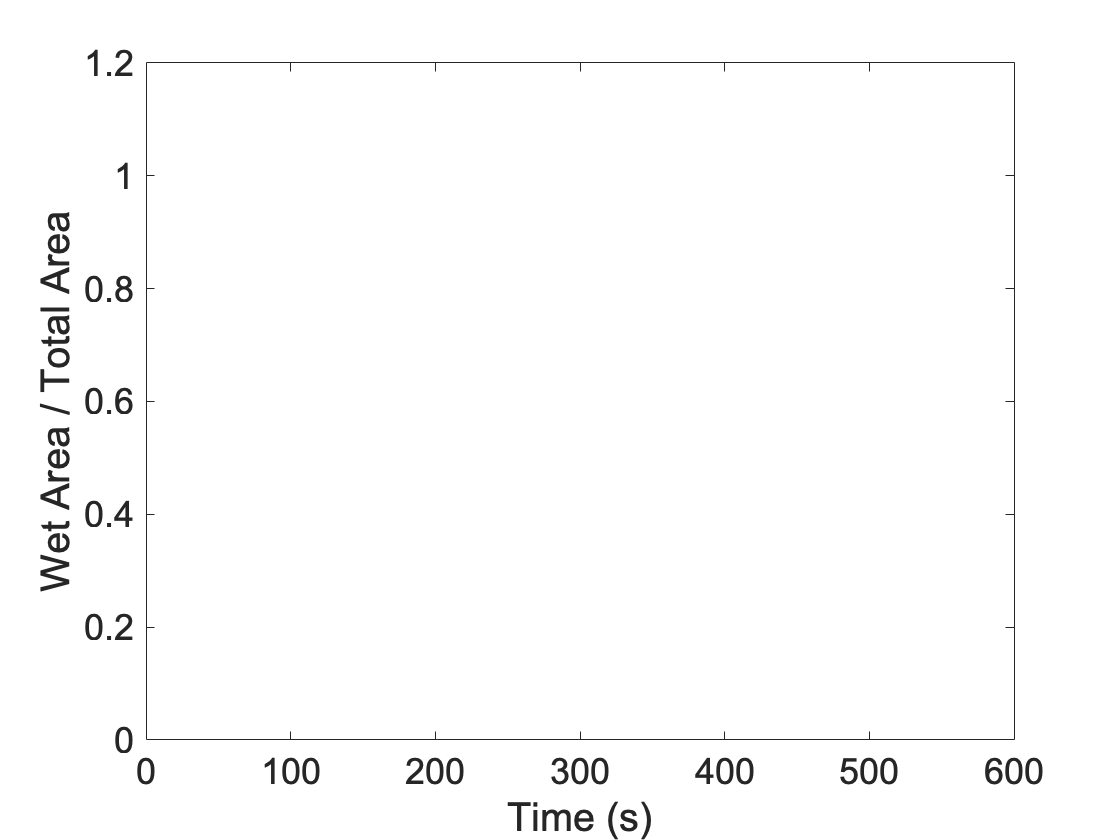

%Re-normalize area 
Norm_area=1-(grain_areas./(max_area-cameraarea));
%Create time array;
time = zeros(1,(floor((nframes-1)/skip_frame)*skip_frame + 1));   %initialize time
for i=1:skip_frame:nframes
    time(i)=(i-t_0)*(1/input_fps); %adjusts time for skipped frames and initial frame rate
end

% Figure formatting
figure, hold on 
xlim([0 600]);
ylim([0 1.2]);
xlabel('Time (s)','FontSize' , 28,'FontName'   , 'Arial')
ylabel('Wet Area / Total Area','FontSize' , 20,'FontName'   , 'Arial')
set( gca,'FontName', 'Arial','FontSize',18);
set(gcf, 'PaperPositionMode', 'auto');
box on;


dewet_data_size = floor((nframes-1)/skip_frame + 1);
dewet_data = zeros(dewet_data_size, 2);
j0 = 0;

for i = 1:skip_frame:nframes
    j0 = j0 + 1;
    dewet_data(j0,:) = [time(i), Norm_area(i)];
end

if(plot_video==1) %plots video of plot
    %Plot video settings
    hold on;
    output_framerate=15;
    outputVideo=VideoWriter(strcat(fname,'_plot'),'MPEG-4');
    outputVideo.FrameRate = output_framerate;
    open(outputVideo);
    
    plot_movie = repmat(struct(getframe(gcf)),1,floor((nframes-1)/skip_frame)*skip_frame + 1); %initialize plot_movie
    for i=1:skip_frame:nframes
        plot(time(i),Norm_area(i),'o')
        plot_movie(i)=getframe(gcf);
        writeVideo(outputVideo,plot_movie(1,i));
    end

    close(outputVideo);
end

## Generate preview plot

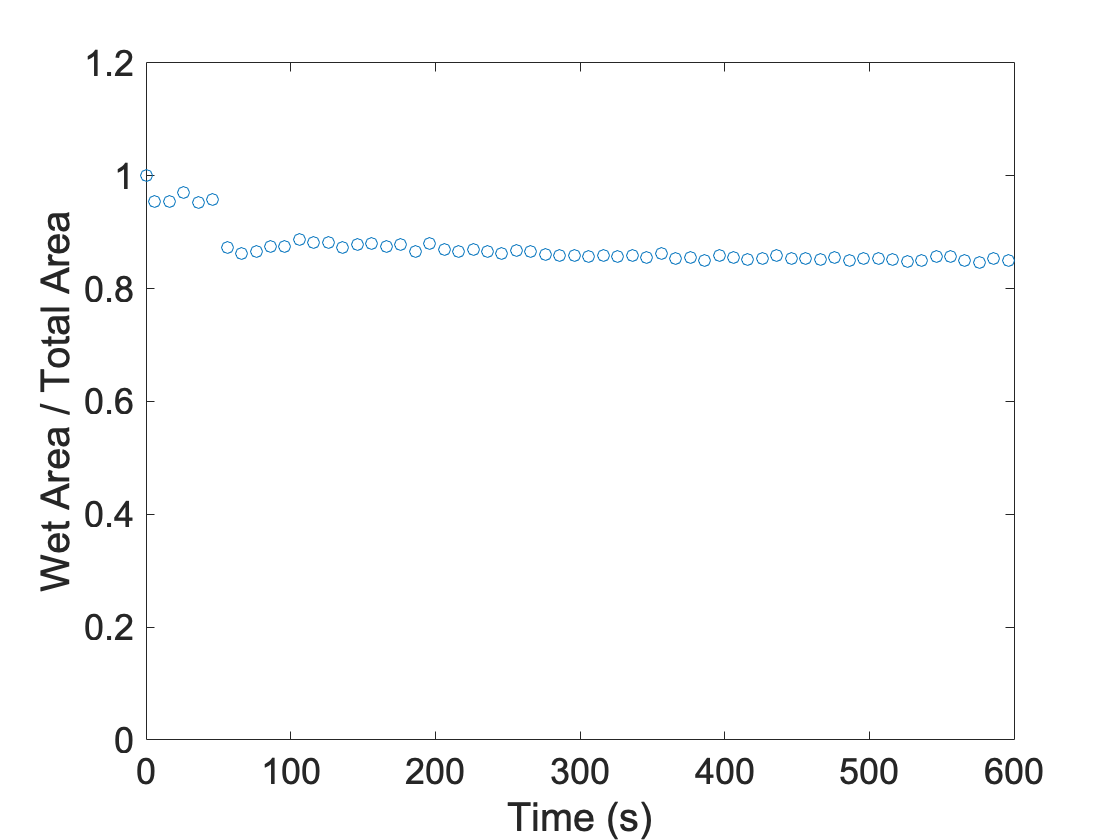

plot(time,Norm_area,'o');
print('-dtiff',strcat(fname,'_graph.tiff'));

## Store analyzed data into text file to be used with image processing code

time=time';Norm_area=Norm_area';
fid=fopen(strcat(fname,'_Area.txt'),'w');
fprintf(fid, '%d %d \n', [dewet_data]');
fclose(fid);

## Store all data (including skipped frames) into text file

fid=fopen(strcat(fname,'_alldata.txt'),'w');
fprintf(fid, '%d %d \n', [time Norm_area]');
fclose(fid);

## Store image processing parameters into text file

fid=fopen(strcat(fname,'_Parameters.txt'),'w'); %saves parameters used in file for analysis 
fprintf(fid, 'remove_Pixels = %d \n', remove_Pixels);
fprintf(fid, 't_0 = %d \n', t_0);
fprintf(fid, 'bg = %d \n', bg);
fprintf(fid, 'frame for area analysis = %d \n', area_frame);
fprintf(fid, 'frames_skipped = %d \n', skip_frame);
fprintf(fid, 'HueThreshold = (%.3f,%.3f) \n', hueThresholdLow, hueThresholdHigh);
fprintf(fid, 'SaturationThreshold = (%.3f,%.3f) \n', saturationThresholdLow, saturationThresholdHigh);
fprintf(fid, 'ValueThreshold = (%.3f,%.3f)', valueThresholdLow, valueThresholdHigh);
fclose(fid);

## Switch warnings on back again

warning('on','all');

# Supporting functions

Use a custom wait function to block the MATLAB command line while you interact with the rectangle. This example specifies a function called `customWait` (defined at the end of the example).

While the command line is blocked, resize and reposition the rectangle so that it encompasses one pear. Double-click on the rectangle to resume execution of the `customWait` function. 

This is the custom wait function that blocks the program execution when you click an ROI. When you have finished interacting with the ROI, the function returns the position of the ROI. 

function customWait(hROI)
    % Listen for mouse clicks on the ROI
    l = addlistener(hROI,'ROIClicked',@clickCallback);
    
    % Block program execution
    uiwait;
    
    % Remove listener
    delete(l);
    
    % Return the current position
end

This click callback function resumes program execution when you double-click the ROI. Note that event data is passed to the callback function as an [`images.roi.ROIClickedEventData`](docid:images_ref.mw_81029a52-9470-4901-a436-7fd4180ba6a7) object, which enables you to define callback functions that respond to different types of actions. For example, you could define a callback function to resume program execution when you click the ROI while pressing the Shift key or when you click a specific part of the ROI such as the label.

function clickCallback(~,evt)
    if strcmp(evt.SelectionType,'double')
        uiresume;
    end
end